# Explore different type of probability density function

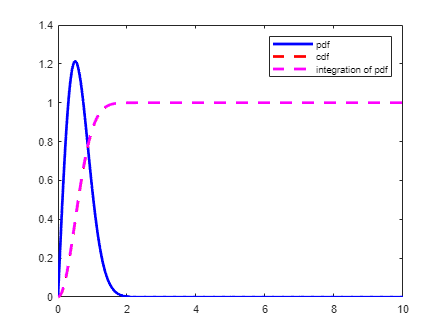

% Rayleigh distribution
scale_parameter =0.5;
resolution_x = 0.01;

x= [0:resolution_x:10];
pdf_rayleigh = (x/scale_parameter^2).*exp(-x.^2/(2*scale_parameter^2));
cdf_rayleigh = 1-exp(-x.^2/(2*scale_parameter^2));
for c= 1:length(pdf_rayleigh)
    int_pdf_rayleigh(c) = sum(pdf_rayleigh([1:c]))*resolution_x;
end    

plot(x, pdf_rayleigh, '-b')
hold on;
plot(x, cdf_rayleigh, '--r')
hold on;
plot(x, int_pdf_rayleigh, '--m')
hold off;
legend('pdf', 'cdf','integration of pdf');

title('Rayleigh pdf/cdf');

standard_deviation = std(pdf_rayleigh);

